# Correlation integral dependence on aromatic, sidechain, and backbone parameters

Plot average and standard deviation of correlation integral for all different sets of parameters.

## Read in Data

fileLocation = '/home/rachael/cluster/scratch/ramansbach/coarsegraining/hoomd/patchy/analyze/production_runs/';
AAnames = {'250','500','750'};
SCnames = {'02','09','2','6','10'};
Signames = {'100','125','150','175'};
Rnames = Signames;
%track different types of parameters/clustering types
colors = {};
c1 = [0 0.4470 0.7410];
c2 = [0.8500 0.3250 0.0980];
c3 = [0.9290 0.6940 0.1250];
c4 = [0.4940 0.1840 0.5560];
c5 = [0.4660 0.6740 0.1880];
c6 =  [0.3010 0.7450 0.9330];
c7 = [0.6350 0.0780 0.1840];
c8 = [0,0,0];
c9 = [1,0,0];
c10 = [0,0,1];
cs = {c1,c2,c3,c4,c5,c6,c7,c8,c9,c10};

tframes = [999];%210:200:1999;
addpath('/home/rachael/Analysis_and_run_code/lab_notebook/CG_patchy/helper_fcns');
dataCell = readFractalDim(tframes,AAnames,SCnames,Signames,fileLocation);

Okay two things:

First, there's an obvious region break according to the variance, and we can do a local min search where we fit three lines to the variance to pick the exact breaks.

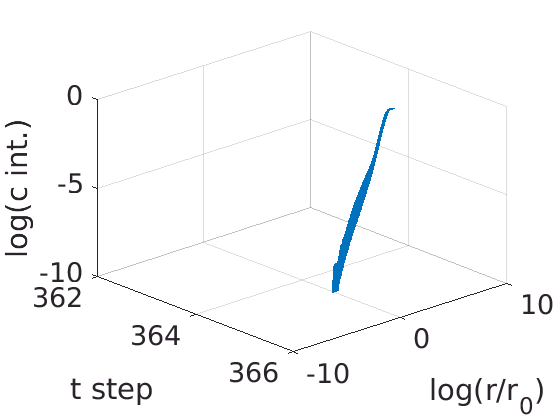

figure()
hold on
set(gca,'fontsize',20)
yMeans = [];
yind = 1;
runs = 5;
for a = 1:length(AAnames)
    for sc = 1:length(SCnames)
        for sig = 1:length(Rnames)
            dataMatrix = dataCell{a}{sc}{sig};
            if ~isempty(dataMatrix)
                
                for t = 1:length(tframes)
                    for run = 1:runs
                        x = dataMatrix(:,1,t);
                        y = dataMatrix(:,1+run,t);
                        c = reshape(log(dataMatrix(83,1+run,:)),[1 length(tframes)]);
                        c2 = reshape(log(dataMatrix(20,1+run,:)),[1 length(tframes)]);
                        plot3(0.365*tframes(t)*ones(size(x)),log(x),log(y),'linewidth',1.5,'color',cs{t})
                        plot3(0.365*tframes,log(x(83))*ones(size(tframes)),c,'r');
                        %plot3(tframes,log(x(20))*ones(size(tframes)),c2,'r');
                    end
                end
                %plot3(tframes,log(x(83))*ones(size(tframes)),log(dataMatrix(83,2:end)),'r')
                %plot3(tframes,log(x(150))*ones(size(tframes)),log(dataMatrix(150,2:end)),'r')
                %plot3(tframes,log(x(20))*ones(size(tframes)),log(dataMatrix(20,2:end)),'r')
                grid on
                view(47.5,30)
                zlabel('log(c int.)')
                ylabel('log(r/r_0)')
                xlabel('t step')
                
            end
        end
    end
end
zlim([-10 0])

%savefig([saveloc 'Correlation_Integral_Convergence'])
%saveas(gcf,[saveloc 'Correlation_Integral_Convergence'],'pdf')

dataCellFinal = {};
yMeans = [];
x = dataMatrix(:,1,1);
for a = 1:length(AAnames)
    for sc = 1:length(SCnames)
       for sig = 1:length(Rnames)
          dataMatrix = dataCell{a}{sc}{sig};
          dataCellFinal{a}{sc}{sig} = dataMatrix(:,:,end); 
          ys = dataMatrix(:,2:end,end);
          yMeans = [yMeans ys];
       end
    end
end


Okay, let's go ahead and investigate the collapse of *all* the runs together, both the ones that are independent and the ones that are for different parameter sizes.  Since they all collapse, it seems fine to look at their spreads like this.

xsig = log(x(~isnan(std(log(yMeans),0,2))));
sigma = std(log(yMeans),0,2);
sigma = sigma(~isnan(sigma));
imax = find(abs(xsig-4.8)==min(abs(xsig-4.8)));
xsig = xsig(1:imax);
sigma = sigma(1:imax);

checkNo = 20; %check 20 points to either side
iguess1 = find(abs(xsig-2)==min(abs(xsig-2)));
iguess2 = find(abs(xsig-3.5)==min(abs(xsig-3.5)));
lf = fittype('a*x+b','independent','x');
minerr = Inf;
warning('off','curvefit:fit:noStartPoint')
for i1 = iguess1%max(iguess1-checkNo,2):min(iguess1+checkNo,length(sigma)-2)
    for i2 = max(iguess2-checkNo,2):min(iguess2+checkNo,length(sigma)-2)
       [P1,gP1] = fit(xsig(1:i1),sigma(1:i1),lf);
       [P2,gP2] = fit(xsig(i1:i2),sigma(i1:i2),lf);  
       [P3,gP3] = fit(xsig(i2:end),sigma(i2:end),lf);
       %compute total RMSE
       %RMSET = ((j-1)/(length(vals)-1))*RMSE1 + ((length(vals)-j)/(length(vals)-1))*RMSE2,
        RMSET = ((i1-1)/(length(sigma)-1))*gP1.rmse + ((i2-i1)/(length(sigma)-1))*gP2.rmse + ((length(sigma)-i2)/(length(sigma)-1))*gP3.rmse;
        if RMSET < minerr
           minerr = RMSET;
           split1 = i1;
           split2 = i2;
        end
    end
end

figure()
hold on
plot(xsig,sigma,'.','markersize',20)
set(gca,'fontsize',20)
plot([xsig(iguess1) xsig(iguess1)], [0 1.5],'k--','linewidth',2)
plot([xsig(iguess2)],[sigma(iguess2)],'go','linewidth',3,'markersize',10)
plot([xsig(split2)],[sigma(split2)],'rx','markersize',20,'linewidth',4)
i1 = find(abs(xsig-0.9)==min(abs(xsig-0.9)));
x1 = xsig(find(abs(xsig-0.9)==min(abs(xsig-0.9))))

x1 = 0.9159

x2 = xsig(split2)

x2 = 3.4057

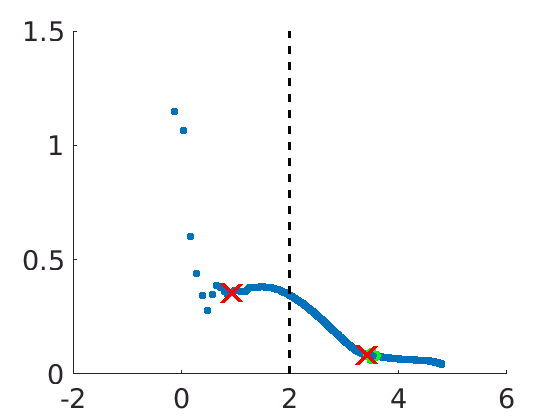

plot([x1],[sigma(i1)],'rx','markersize',20,'linewidth',4)

Check a linear fit for the collapsed region.

## Plot Data

For each non empty piece of data, get the mean and the standard deviation and plot it on the figure.

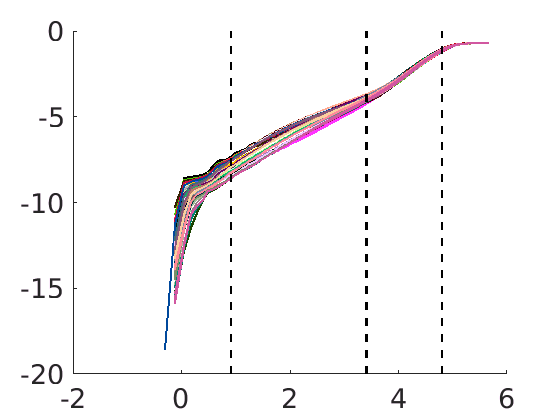

figure()
set(gca,'fontsize',20)
hold on;
runs = 5;
colormatrix = importdata('/home/rachael/Analysis_and_run_code/lab_notebook/hexcolors.dat');
imaxx = find(abs(log(x)-4.8)==min(abs(log(x)-4.8)));
ind = 1;
fd3s = [];
for a = 1:length(AAnames)
    for sc = 1:length(SCnames)
        for sig = 1:length(Rnames)
            dataMatrix = dataCellFinal{a}{sc}{sig};
            if ~isempty(dataMatrix)
                x = dataMatrix(:,1);
                %y = mean(dataMatrix(:,2:end),2);
                %yMeans(:,yind) = y;
                
                %yind = yind + 1;
                %s = std(dataMatrix(:,2:end),0,2);
                %errorbar(x,y,s,'linewidth',2)
                for run = 1:runs
                    y = dataMatrix(:,1+run);
                    plot(log(x),log(y),'-','linewidth',1.5,'color',colormatrix(ind,:))
                    lf = fittype('a*x+b','independent','x');
                    [P1,gP1] = fit(log(x(split2:imaxx)),log(y(split2:imaxx)),lf);
                    fd3s = [fd3s P1.a];
                end
                ind = ind + 1;
                %xlim([log(1.5) log(73.3)])
                %xlim([0 4.5])
                
                %ylim([-15 0])
            end
        end
    end
end
plot(4.8*ones(size(-21:1)),-21:1,'--k','linewidth',2)
plot(x2*ones(size(-21:1)),-21:1,'--k','linewidth',2)
plot(x1*ones(size(-21:1)),-21:1,'--k','linewidth',2)
ylim([-20 0])

%patch([log(5) log(12) log(12) log(5)],[-21 -21 1 1],'r','facealpha',0.3,'edgecolor','None')

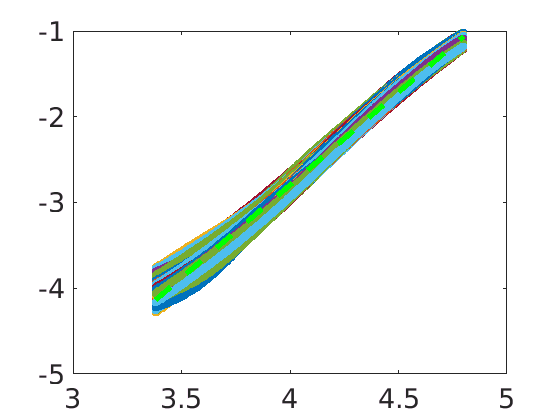

figure()
imaxx = find(abs(log(x)-4.8)==min(abs(log(x)-4.8)));
lf = fittype('a*x+b','independent','x');
plot(log(x(split2:imaxx)),log(yMeans(split2:imaxx,:)),'.','markersize',20)
set(gca,'fontsize',20)
[P1,gP1] = fit(log(x(split2:imaxx)),mean(log(yMeans(split2:imaxx,:)),2),lf);
hold on
plot(log(x(split2:imaxx)),P1(log(x(split2:imaxx))),'g--','linewidth',4)

cia = confint(P1);
cia = cia(:,1);
fprintf('Dimension is %f (%f,%f)',P1.a,cia(1),cia(2));

Dimension is 2.164068 (2.157483,2.170652)

fprintf('Mean dimension is %f +/- %f',mean(fd3s),std(fd3s));

Mean dimension is 2.164068 +/- 0.054724

Second, it's unclear as to whether a single linear fit or two is better for that central region, so use AIC to determine that for each run.

addpath('/home/rachael/Analysis_and_run_code/stats_analysis/');
saveloc = '/home/rachael/coarsegraining/Data/patchy';
figure()
dims = zeros(length(AAnames)*length(SCnames)*length(Rnames),9);
D1s = zeros(length(AAnames)*length(SCnames)*length(Rnames),runs);
D2s = zeros(length(AAnames)*length(SCnames)*length(Rnames),runs);
runs = 5;
tic
%for a = 1:length(AAnames)
%    for sig = 1:length(Rnames)
ind = 1;
a = 1;
for sc = 1:length(SCnames)
    for sig = 1:length(Rnames)
        runLdim
    end
end
toc
save('/home/rachael/coarsegraining/Data/patchy/fdims.mat');

tic
a = 2;
for sc = 1:length(SCnames)
    for sig = 1:length(Rnames)
        runLdim
    end
end
toc
save('/home/rachael/coarsegraining/Data/patchy/fdims.mat');

tic
a = 3;
for sc = 1:length(SCnames)
    for sig = 1:length(Rnames)
        runLdim
    end
end
toc
save('/home/rachael/coarsegraining/Data/patchy/fdims.mat');

dims(:,3) = dims(:,3)/100;
save('/home/rachael/coarsegraining/Data/patchy/fdims.mat');

## Now let's investigate these dimensions as a function of our parameter space

**Region 1**

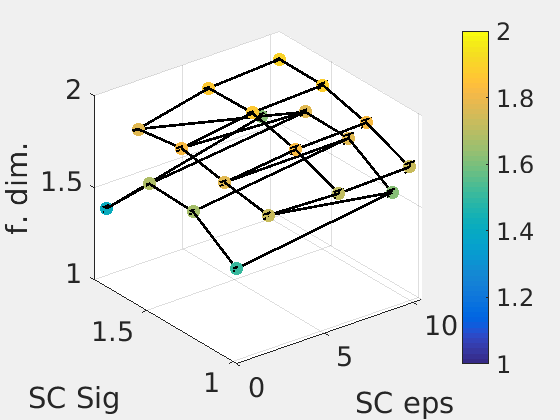

load('/home/rachael/coarsegraining/Data/patchy/fdims.mat');

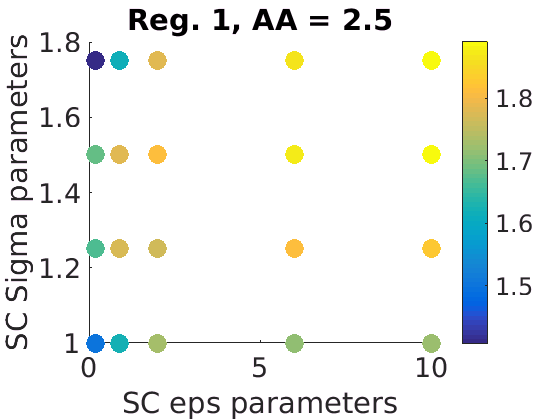

saveloc = '/home/rachael/coarsegraining/Data/patchy';
addpath('/home/rachael/Analysis_and_run_code/lab_notebook/CG_patchy');
addpath('/home/rachael/Analysis_and_run_code/lab_notebook/CG_patchy/helper_fcns');
figure()
hold on


i02 = find((dims(:,1)==2.5) & (dims(:,6) ~=0));
i01 = find((dims(:,1)==2.5) & (dims(:,6) ==0));
scatter(dims(i01,2),dims(i01,3),200,dims(i01,4))
scatter(dims(i02,2),dims(i02,3),200,dims(i02,4),'filled')
colorbar
caxis([min(dims(:,4)) max(dims(:,4))])
set(gca,'fontsize',20)
xlabel('SC eps parameters')
ylabel('SC Sigma parameters')
title('Reg. 1, AA = 2.5')
savefig([saveloc '/dimr1A250'])
saveas(gcf,[saveloc '/dimr1A250'],'pdf')

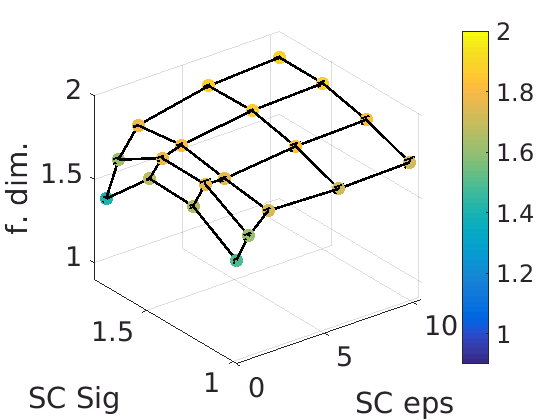


f = figure();
hold on
f = errorMesh(dims(i02,2),dims(i02,3),dims(i02,4),dims(i02,7)/sqrt(runs),[0 0 0],f,0.3);
figure(f);
colorbar
%caxis([min(dims(:,4)) max(dims(:,4))])
xlim([0 10.5])
ylim([0.98 1.8])
caxis([0.9 2])
zlim([0.9 2])%zlim([min(dims(:,4)-dims(:,7)) max(dims(:,4)+dims(:,7))])
view([-37.5,30])
set(gca,'fontsize',20);
xlabel('SC eps')
ylabel('SC Sig')
zlabel('f. dim.')
savefig([saveloc '/dimr1A2503D'])
saveas(gcf,[saveloc '/dimr1A2503D'],'pdf')

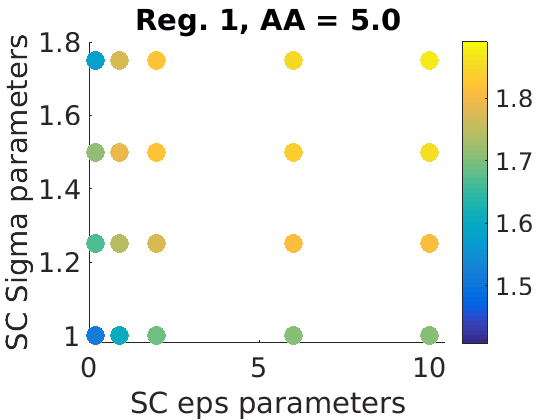

figure()
hold on

i02 = find((dims(:,1)==5) & (dims(:,6) ~=0));
i01 = find((dims(:,1)==5) & (dims(:,6) ==0));
scatter(dims(i01,2),dims(i01,3),200,dims(i01,4))
scatter(dims(i02,2),dims(i02,3),200,dims(i02,4),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('SC eps parameters')
ylabel('SC Sigma parameters')
title('Reg. 1, AA = 5.0')
caxis([min(dims(:,4)) max(dims(:,4))])
xlim([0 10.5])
ylim([0.98 1.8])
savefig([saveloc '/dimr1A500'])
saveas(gcf,[saveloc '/dimr1A500'],'pdf')

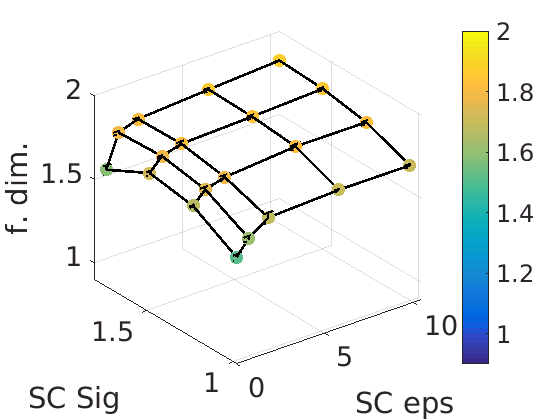


f = figure();
hold on

f = errorMesh(dims(i02,2),dims(i02,3),dims(i02,4),dims(i02,7)/sqrt(runs),[0 0 0],f,0.3);
figure(f);
colorbar

xlim([0 10.5])
ylim([0.98 1.8])
caxis([0.9 2])
zlim([0.9 2])
view([-37.5,30])
set(gca,'fontsize',20);
xlabel('SC eps')
ylabel('SC Sig')
zlabel('f. dim.')
savefig([saveloc '/dimr1A5003D'])
saveas(gcf,[saveloc '/dimr1A5003D'],'pdf')

figure()
hold on

i02 = find((dims(:,1)==7.5) & (dims(:,6) ~=0));
i01 = find((dims(:,1)==7.5) & (dims(:,6) ==0));
scatter(dims(i01,2),dims(i01,3),200,dims(i01,4))
scatter(dims(i02,2),dims(i02,3),200,dims(i02,4),'filled')
colorbar
caxis([min(dims(:,4)) max(dims(:,4))])
set(gca,'fontsize',20)
xlabel('SC eps parameters')
ylabel('SC Sigma parameters')
title('Reg. 1, AA = 7.5')

savefig([saveloc '/dimr1A750'])
saveas(gcf,[saveloc '/dimr1A750'],'pdf')


f = figure();
hold on

f = errorMesh(dims(i02,2),dims(i02,3),dims(i02,4),dims(i02,7)/sqrt(runs),[0 0 0],f,0.3);
figure(f);
colorbar

xlim([0 10.5])
ylim([0.98 1.8])
caxis([0.9 2])
zlim([0.9 2])
view([-37.5,30])
set(gca,'fontsize',20);
xlabel('SC eps')
ylabel('SC Sig')
zlabel('f. dim.')
savefig([saveloc '/dimr1A7503D'])
saveas(gcf,[saveloc '/dimr1A7503D'],'pdf')

**Region 2**

figure()
hold on

i02 = find((dims(:,1)==2.5) & (dims(:,6) ~=0));
i01 = find((dims(:,1)==2.5) & (dims(:,6) ==0));
scatter(dims(i01,2),dims(i01,3),200,dims(i01,5))
scatter(dims(i02,2),dims(i02,3),200,dims(i02,5),'filled')
colorbar
caxis([min(dims(:,5)),max(dims(:,5))])
set(gca,'fontsize',20)
xlabel('SC eps parameters')
ylabel('SC Sigma parameters')
title('Reg. 2, AA = 2.5')
savefig([saveloc '/dimr2A250'])
saveas(gcf,[saveloc '/dimr2A250'],'pdf')

f = figure();
hold on

f = errorMesh(dims(i02,2),dims(i02,3),dims(i02,5),dims(i02,8)/sqrt(5),[0 0 0],f,0.3);
figure(f);
colorbar
xlim([0 10.5])
ylim([0.98 1.8])
caxis([0.9 2])
zlim([0.9 2])
set(gca,'fontsize',20);
xlabel('SC eps')
ylabel('SC Sig')
zlabel('f. dim.')
view([-37.5,30])
savefig([saveloc '/dimr2A2503D'])
saveas(gcf,[saveloc '/dimr2A2503D'],'pdf')


figure()
hold on

i02 = find((dims(:,1)==5) & (dims(:,6) ~=0));
i01 = find((dims(:,1)==5) & (dims(:,6) ==0));
scatter(dims(i01,2),dims(i01,3),200,dims(i01,5))
scatter(dims(i02,2),dims(i02,3),200,dims(i02,5),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('SC eps parameters')
ylabel('SC Sigma parameters')
title('Reg. 2, AA = 5.0')
caxis([min(dims(:,5)),max(dims(:,5))])
savefig([saveloc '/dimr2A500'])
saveas(gcf,[saveloc '/dimr2A500'],'pdf')

f = figure();
hold on

f = errorMesh(dims(i02,2),dims(i02,3),dims(i02,5),dims(i02,8)/sqrt(5),[0 0 0],f,0.3);
figure(f);
colorbar
xlim([0 10.5])
ylim([0.98 1.8])
caxis([0.9 2])
zlim([0.9 2])
set(gca,'fontsize',20);
xlabel('SC eps')
ylabel('SC Sig')
zlabel('f. dim.')
view([-37.5,30])
savefig([saveloc '/dimr2A5003D'])
saveas(gcf,[saveloc '/dimr2A5003D'],'pdf')


figure()
hold on

i02 = find((dims(:,1)==7.5) & (dims(:,6) ~=0));
i01 = find((dims(:,1)==7.5) & (dims(:,6) ==0));
scatter(dims(i01,2),dims(i01,3),200,dims(i01,5))
scatter(dims(i02,2),dims(i02,3),200,dims(i02,5),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('SC eps parameters')
ylabel('SC parameters')
title('Reg. 2, AA = 7.5')
caxis([min(dims(:,5)),max(dims(:,5))])
savefig([saveloc '/dimr2A750'])
saveas(gcf,[saveloc '/dimr2A750'],'pdf')

f = figure();
hold on

f = errorMesh(dims(i02,2),dims(i02,3),dims(i02,5),dims(i02,8)/sqrt(5),[0 0 0],f,0.3);
figure(f);
colorbar

xlim([0 10.5])
ylim([0.98 1.8])
caxis([0.9 2])
zlim([0.9 2])
set(gca,'fontsize',20);
xlabel('SC eps')
ylabel('SC Sig')
zlabel('f. dim.')
view([-37.5,30])
savefig([saveloc '/dimr2A7503D'])
saveas(gcf,[saveloc '/dimr2A7503D'],'pdf')

## Division between regions

mdiv = mean(dims(:,6));
smdiv = std(dims(:,6));
fprintf('The mean turnover between regions is: %f +/- %f nm',mdiv,smdiv)
figure()
hist(dims(:,6),50)

figure()
hold on
%colormap copper
i02 = find((dims(:,1)==2.5) & (dims(:,6) ~=0));
i01 = find((dims(:,1)==2.5) & (dims(:,6) ==0));
scatter(dims(i01,2),dims(i01,3),200,dims(i01,6))
scatter(dims(i02,2),dims(i02,3),200,dims(i02,6),'filled')
colorbar
caxis([min(dims(:,6)) max(dims(:,6))])
set(gca,'fontsize',20)
xlabel('SC eps parameters')
ylabel('SC Sigma parameters')
title('Reg. Div., AA = 2.5')
savefig([saveloc '/dimrdivA250'])
saveas(gcf,[saveloc '/dimrdivA250'],'pdf')

f = figure();
hold on

f = errorMesh(dims(i02,2),dims(i02,3),dims(i02,6),dims(i02,9)/sqrt(5),[0 0 0],f,0.3);
figure(f);
colorbar
caxis([min(dims(:,6)) max(dims(:,6))])
xlim([0 10.5])
ylim([0.98 1.8])
zlim([min(dims(:,6)-dims(:,9)) max(dims(:,6)+dims(:,9))])
set(gca,'fontsize',20);
xlabel('SC eps')
ylabel('SC Sig')
zlabel('f. dim.')
savefig([saveloc '/dimrdivA2503D'])
saveas(gcf,[saveloc '/dimrdivA2503D'],'pdf')


figure()
hold on
%colormap copper
i02 = find((dims(:,1)==5) & (dims(:,6) ~=0));
i01 = find((dims(:,1)==5) & (dims(:,6) ==0));
scatter(dims(i01,2),dims(i01,3),200,dims(i01,6))
scatter(dims(i02,2),dims(i02,3),200,dims(i02,6),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('SC eps parameters')
ylabel('SC Sigma parameters')
title('Reg. Div., AA = 5.0')
caxis([min(dims(:,6)) max(dims(:,6))])
savefig([saveloc '/dimrdivA500'])
saveas(gcf,[saveloc '/dimrdivA500'],'pdf')

f = figure();
hold on

f = errorMesh(dims(i02,2),dims(i02,3),dims(i02,6),dims(i02,9)/sqrt(5),[0 0 0],f,0.3);
figure(f);
colorbar
caxis([min(dims(:,6)) max(dims(:,6))])
xlim([0 10.5])
ylim([0.98 1.8])
zlim([min(dims(:,6)-dims(:,9)) max(dims(:,6)+dims(:,9))])
set(gca,'fontsize',20);
xlabel('SC eps')
ylabel('SC Sig')
zlabel('f. dim.')
savefig([saveloc '/dimrdivA5003D'])
saveas(gcf,[saveloc '/dimrdivA5003D'],'pdf')


figure()
hold on
%colormap copper
i02 = find((dims(:,1)==7.5) & (dims(:,6) ~=0));
i01 = find((dims(:,1)==7.5) & (dims(:,6) ==0));
scatter(dims(i01,2),dims(i01,3),200,dims(i01,6))
scatter(dims(i02,2),dims(i02,3),200,dims(i02,6),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('SC eps parameters')
ylabel('SC parameters')
title('Reg. Div., AA = 7.5')
caxis([min(dims(:,6)) max(dims(:,6))])
savefig([saveloc '/dimrdivA750'])
saveas(gcf,[saveloc '/dimrdivA750'],'pdf')

f = figure();
hold on

f = errorMesh(dims(i02,2),dims(i02,3),dims(i02,6),dims(i02,9)/sqrt(5),[0 0 0],f,0.3);
figure(f);
colorbar
caxis([min(dims(:,6)) max(dims(:,6))])
xlim([0 10.5])
ylim([0.98 1.8])
zlim([min(dims(:,6)-dims(:,9)) max(dims(:,6)+dims(:,9))])
set(gca,'fontsize',20);
xlabel('SC eps')
ylabel('SC Sig')
zlabel('f. dim.')
savefig([saveloc '/dimrdivA7503D'])
saveas(gcf,[saveloc '/dimrdivA7503D'],'pdf')